clc
close all
clear all
s  = tf('s');
Fs = 1/(1+s*(1/800))

Fs =
 
        1
  -------------
  0.00125 s + 1
 
Continuous-time transfer function.
Model Properties


Fs_d = c2d(Fs,0.001,'ZOH')

Fs_d =
 
    0.5507
  ----------
  z - 0.4493
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


Fs_d.Variable='z^-1'

Fs_d =
 
    0.5507 z^-1
  ---------------
  1 - 0.4493 z^-1
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties



%calcolo i coefficienti di A e di B
numC0d=Fs_d.Numerator{1};
denC0d=Fs_d.Denominator{1};
numC0d=numC0d/denC0d(1);
denC0d=denC0d/denC0d(1);
%y/u = B/A
A=-denC0d(2:end) %uscite precenti

A = 0.4493

B=numC0d % incressi precedenti

B =          0    0.5507


% y = A*y(k-x)+B*u(k-x)
% y = 0.4493*y(k-1) + 0.5507*u(k-1)
filtro = FilterFirstOrder(1/800,0.001)

filtro =   FilterFirstOrder with no properties.

filtro.Discretization

ans =   FilterFirstOrder with no properties.

filtro.Starting

ans =   FilterFirstOrder with no properties.

st = 0.001

st = 1.0000e-03

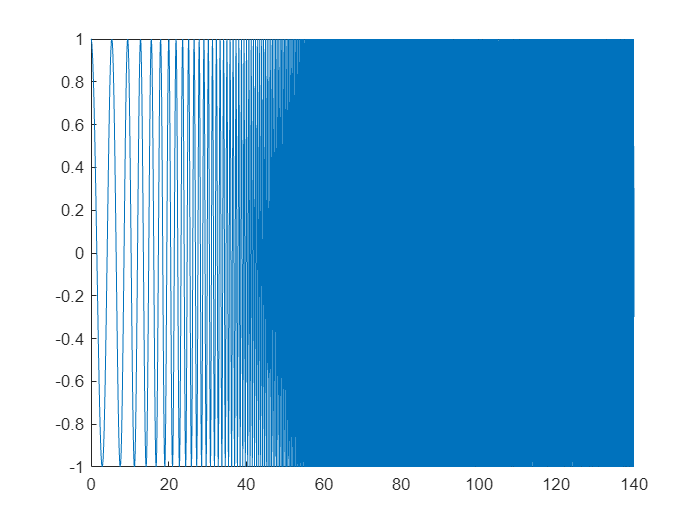

t=(0:st:140)';
w0=1; %rad/s
w1=pi/st; %rad/s     Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts -> valore alto tipo val max dato
control_action = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
figure
plot(t,control_action)

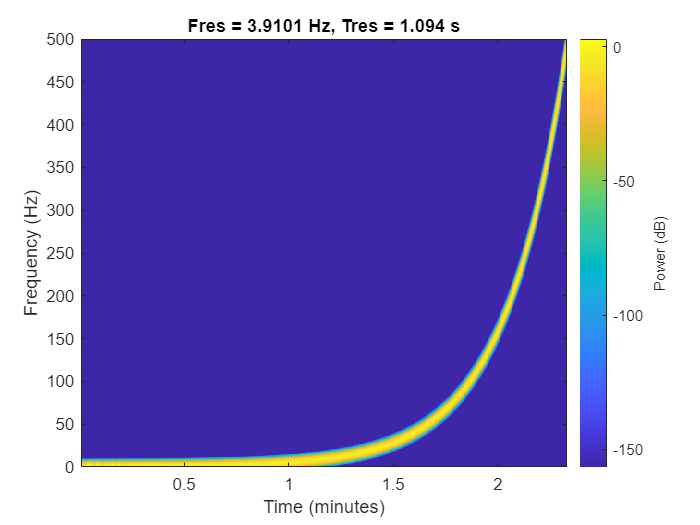

pspectrum(control_action,1/st,'spectrogram');


process_output=zeros(length(t),1);
for idx=1:length(t)
    process_output(idx,:)=filtro.Compute(control_action(idx));
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 0-by-0.

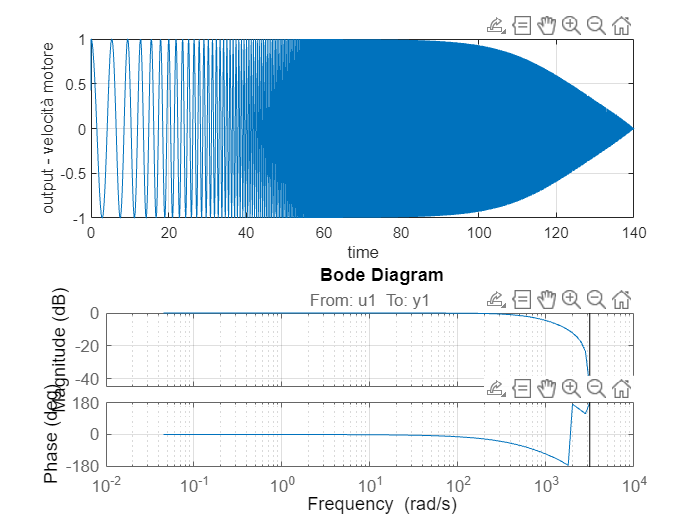


figure(1)
subplot(2,1,1)
plot(t,process_output(:))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

identification=iddata(process_output(:),control_action,st);
freq_resp_ident = spafdr(identification);

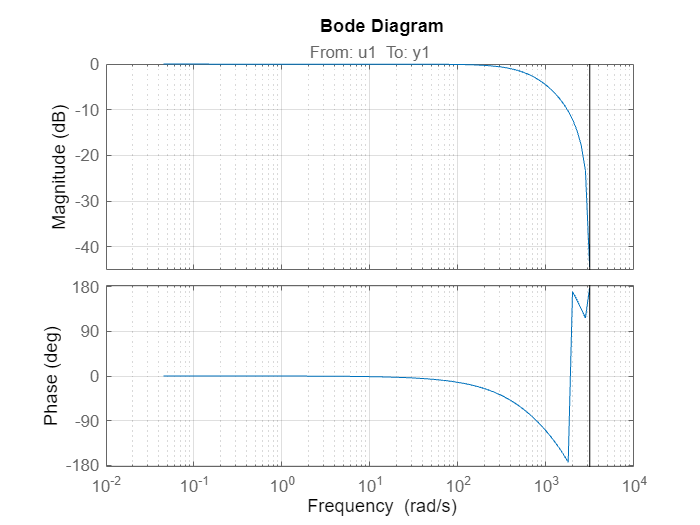

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
